# Aerogen Exercise

- Del Castillo Menéndez, Alberto

- Domínguez Alegre, Carlos F.

- Ramos Arévalo, Víctor

- Silveira Relanzón, Willy

% VARIABLES AND PARAMETERS FOR THE SIMULINK MODEL

Vw=10;      % Wind speed [m/s]
Tf=0.1;     %
Ke=1.3717;  %
Bm=0.001;   % 
J=0.1;      %
R=10;       %
Ra=2.58;    %
La=0.028;   %
Rpala=1.6;  %
Rho=1.225;  %

% coefficients for lambda

c1=0.51763;
c2=116;
c3=0.4;
c4=5;
c5=21;
c6=0.006795;

% Parameters of actuator
wnAct=20; 
psiAct=0.8;
maxDefAct = 0;
minDefAct = -70;
rateLimAct = 50;
initialPosAct = 0; 
initialVelAct = 0;


## TRIMING THE PLANT

 To find the triming point of the plant a new model of the aerogen is generated without the actuator, 

 the actuator makes the trim algorithm to fail (?)

 Select the point around the trim will be done:

X0 = [50;5.5]  % initial condition for the states (in this case angular speed and electrical generator intensity) 

X0 =    50.0000
    5.5000


Y0 = [50]      % initial condition on y -> angular speed

Y0 = 50

U0 = []        % initial condition on u -> whatever


U0 =

     []



Fix some of the components of X, Y or U in the triming process:

iy = [1]       % Constrain Y(1) to be fixed

iy = 1

ix = []        % No constrain over x


ix =

     []



iu = []        % No constrain over u


iu =

     []



Find the triming point on the condition especified above

[X,U,Y,DX,options] = trim('Aerogen2019NoActuator',X0,U0,Y0,ix,iu,iy);
X

X =    50.0000
    5.4519


U

U = -17.3463

## LINEARIZE THE PLANT

Generate the vector state

Xlin = [X(1);U;0;X(2)]

Xlin =    50.0000
  -17.3463
         0
    5.4519


The linmod is called and a transfer funciton is generated: 

%Edit initial position and speed of actuator
initialPosAct = U;
initialVelAct = 0;

trimIntensity = X(2);


[num,den] = linmod('Aerogen2019',Xlin,U);
%[num,den] = linmod('Aerogen2019NoActuator',X,U)

transferFunction = tf(num,den)


transferFunction =
 
                  1.083e04 s + 4.867e06
  ------------------------------------------------------
  s^4 + 492.4 s^3 + 2.078e04 s^2 + 3.648e05 s + 2.258e06
 
Continuous-time transfer function.




% Zeros and poles of tf
zeros = zero(transferFunction);
poles = pole(transferFunction);
zpk(transferFunction)


ans =
 
             10832 (s+449.3)
  -------------------------------------
  (s+447.7) (s+12.61) (s^2 + 32s + 400)
 
Continuous-time zero/pole/gain model.



## DYNAMIC RESPONSE

 **Locus of roots of the system:**

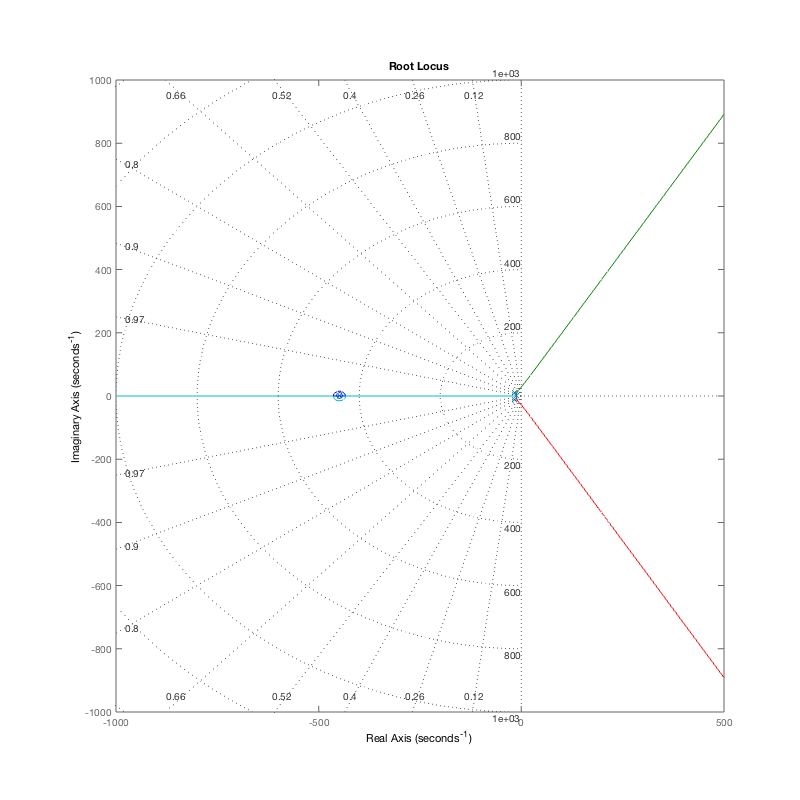

f1 = figure(1);
set(f1,'Position',[10 10 800 800])
rlocus(transferFunction)
grid on

**Bode Diagram:**

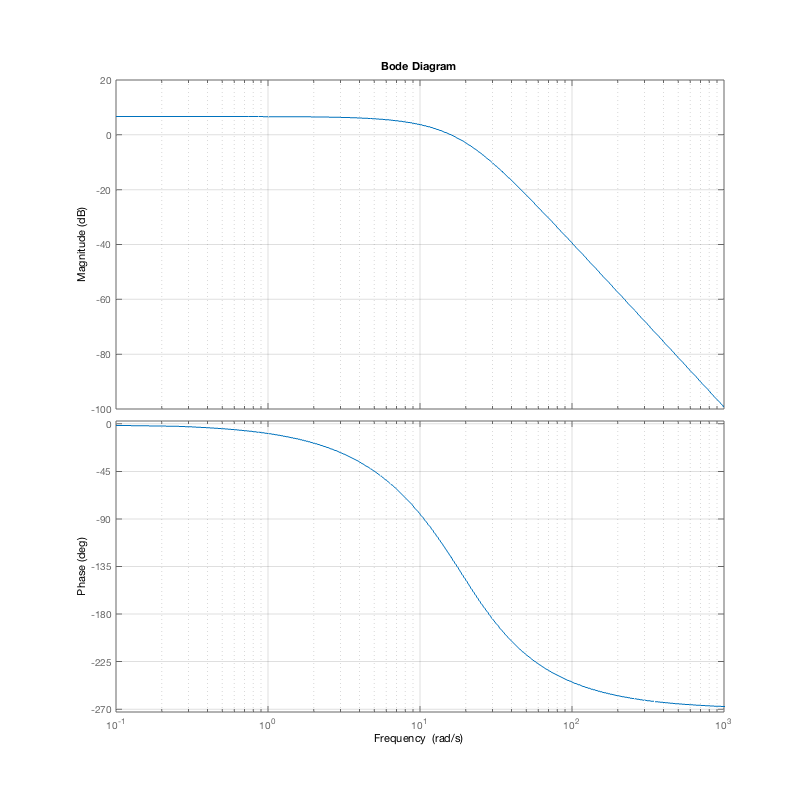

f2 = figure(2);
set(f2,'Position',[10 10 800 800])
bode(transferFunction)
grid on

**Nyquist Diagram: **

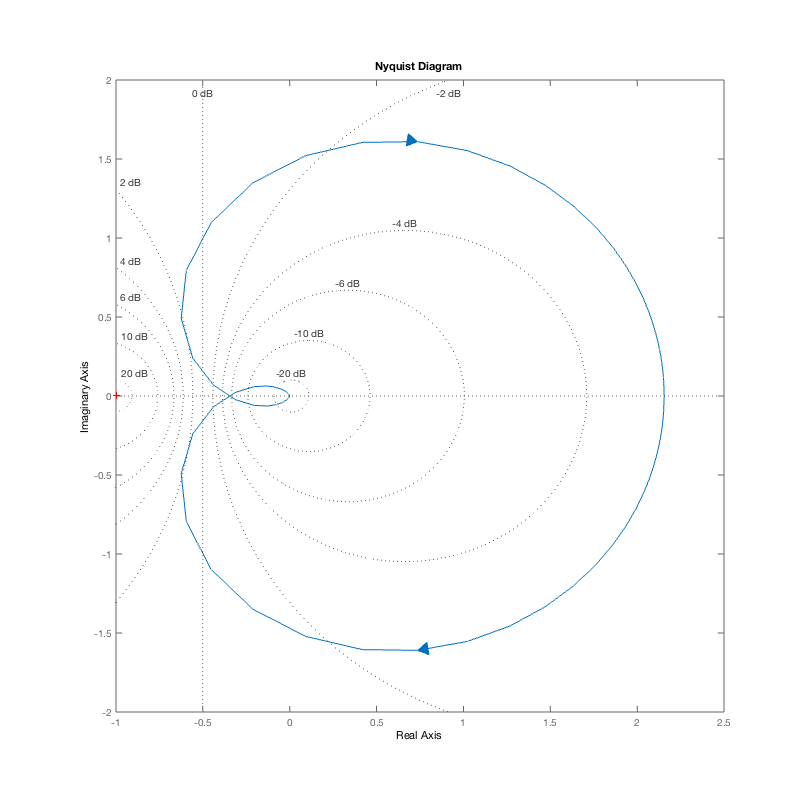

f3 = figure(3);
set(f3,'Position',[10 10 800 800])
nyquist(transferFunction)
grid on

**Step Response:**

f4 = figure(4);
set(f4,'Position',[10 10 800 800])
set(f4,'DefaultAxesFontSize',20)
step(transferFunction)
grid on
hold on

Compare the step response of linear system with real system: for this task a new simulink model is generated, 

all integrators are set to its trim point value and an unitary step is generated at t=0 of the simulation. 

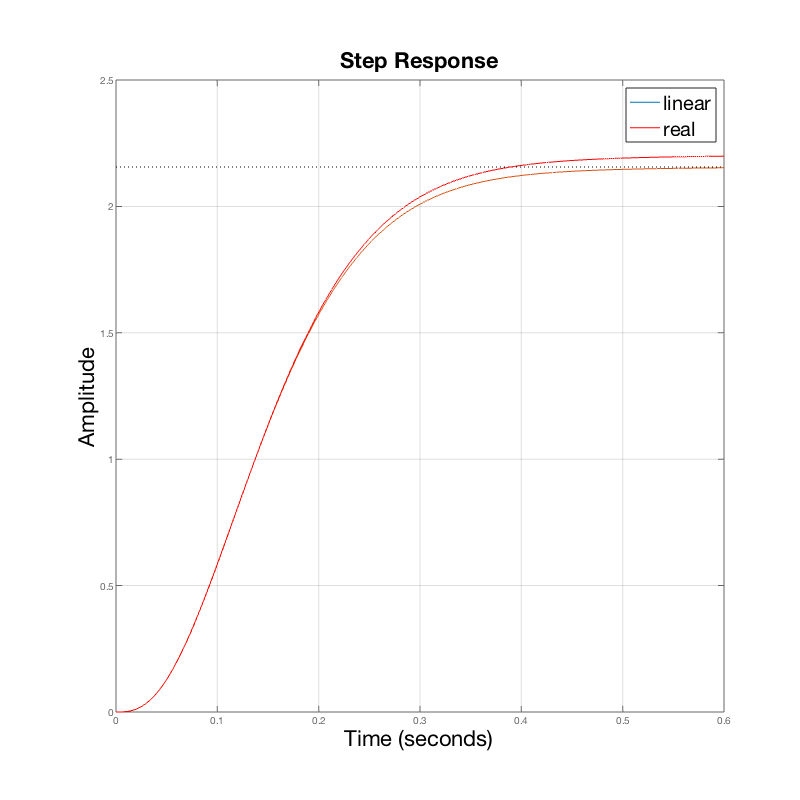

simOut = sim('Aerogen2019Step','OutputSaveName','yout');
outputs = simOut.get('yout');
% Once the simulation is done the result si plotted against the step
% response of the linear system.

plot(outputs(:,2),outputs(:,1),'r')
legend({'linear','real'},'FontSize',20)

## CONTROLLER DESIGN

the first controller is calculated using the Ziegler-Nichols Method N 1.

First the data from the step response of the linear system is gadered and from this data L, and T are calculated.

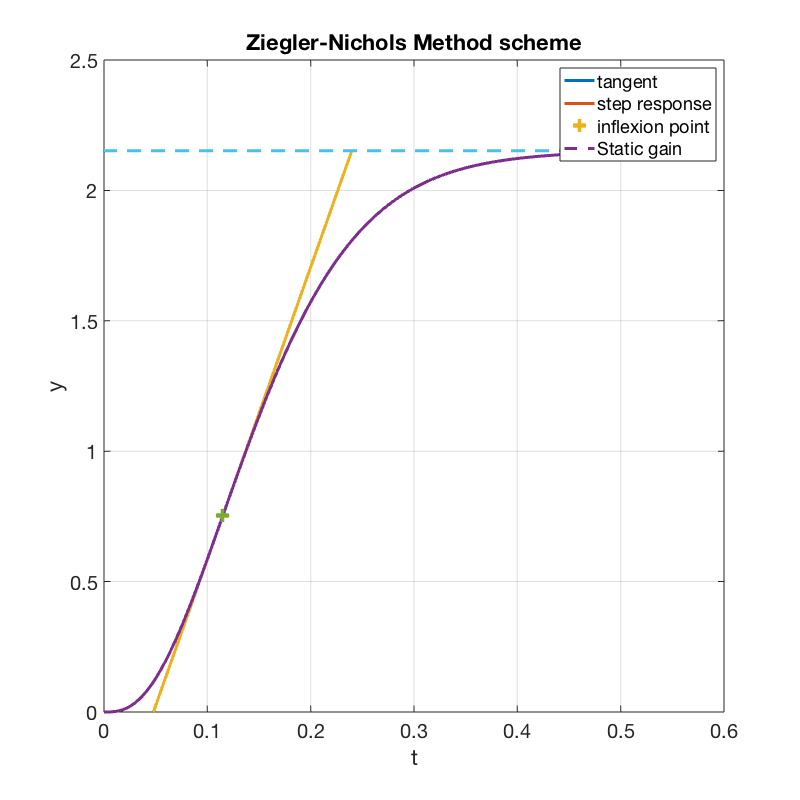

[y_step,t_step,x_step] = step(transferFunction);


dydt = gradient(y_step(:))./gradient(t_step(:));
d2ydt2 = gradient(dydt(:))./gradient(t_step(:));

signs = sign(d2ydt2);
[~,c] = ismember(-1,signs); % finds last index of -1 (positive hess)

Ay = d2ydt2(c-1);     At = t_step(c-1);
By = d2ydt2(c);    Bt = t_step(c);

deltaD2ydt2 = Ay-By;
deltaT = Bt-At;

t_inflex = t_step(c-1) + deltaT*Ay/deltaD2ydt2;
y_inflex = spline(t_step,y_step,t_inflex);
dy_inflex = spline(t_step,dydt,t_inflex); % find the derivate of the funciton in the inflexion
c = y_inflex - t_inflex*dy_inflex;
k = y_step(end);
L = -c/dy_inflex;
TplusL = (k-c)/dy_inflex;
T = TplusL - L;

% the tangent of the curve at the inflexion has the ecuation y =
% dy_inflex*x + c; 

% Plot the scheme...
f5 = figure(5);
set(f5,'Position',[10 10 800 800]);
set(f5,'DefaultAxesFontSize',20);
mytime = linspace(L,T+L);
plot(mytime,mytime*dy_inflex + c, 'LineWidth',3) % tangent

hold on
plot(t_step,y_step, 'LineWidth',3) % actual state
plot(t_inflex,y_inflex,'o', 'LineWidth',12, 'LineWidth',12) % inflexion poin
plot(t_step,ones(1,length(t_step))*k,'--', 'LineWidth',3)
grid on
legend('tangent','step response','inflexion point','Static gain')
title 'Ziegler-Nichols Method scheme'
xlabel 't'
ylabel 'y'

Calculate the gains for PID controller with the rules propoposed by the firts method:

 
Kp = 1.2*T/L

Kp = 4.8197

T_i = 2*L;
T_d = 0.5*L;

Ki = Kp/T_i

Ki = 50.4018

Kd = T_d*Kp

Kd = 0.1152

These gains were found to not perform well, modified are:

Kp

Kp = 4.8197

Ki = Ki/10

Ki = 5.0402

Kd = Kd*10

Kd = 1.1522


f6 = figure(6);
A = imread('ZieglerNicholsPID.jpg');
image(A)
set(f6, 'Units', 'Normalized', 'OuterPosition', [0 0 1 1]);

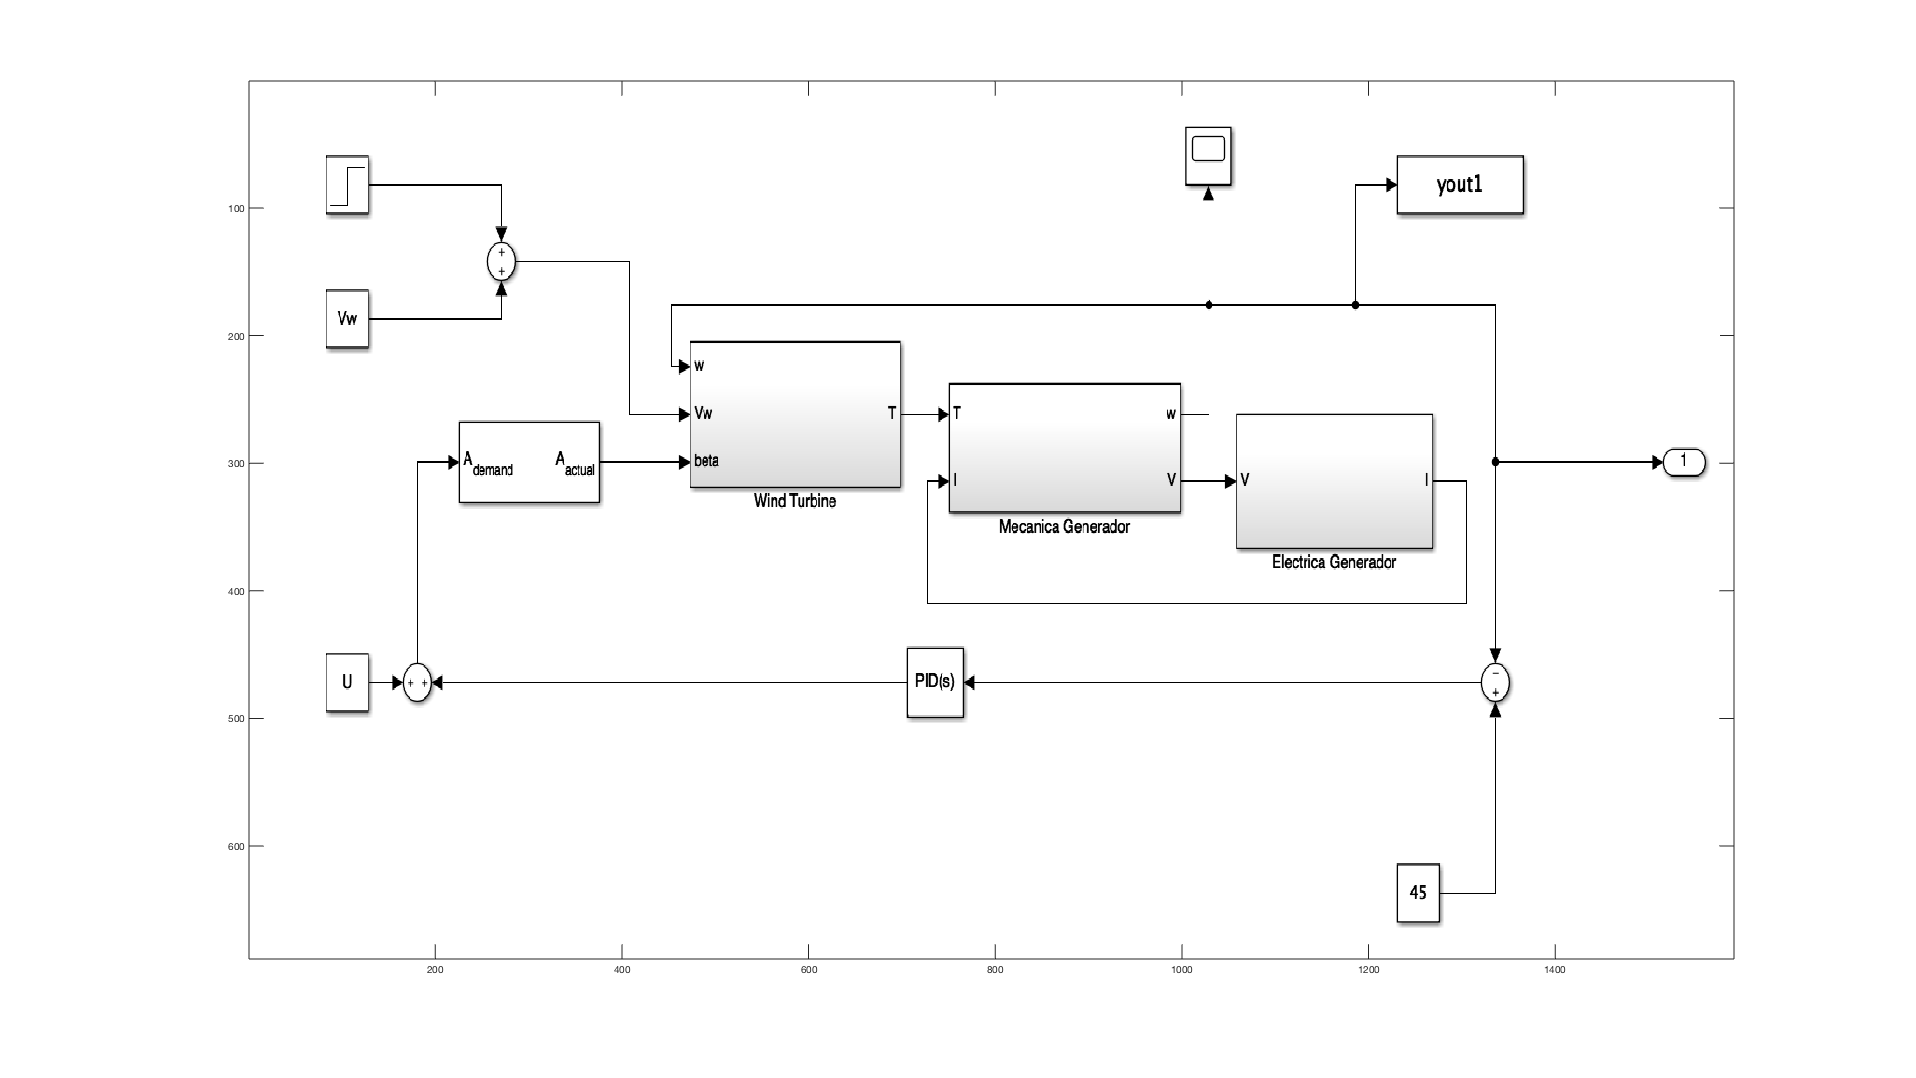


f7 = figure(7);
A = imread('SimulinkPID.png');
image(A)

set(f7, 'Units', 'Normalized', 'OuterPosition', [0 0 1 1]);